% Get user input for carrier frequency and amplitude
prompt1 = "Enter the carrier frequency (Hz): ";
prompt2 = "Enter the carrier amplitude: ";
prompt3 = "Enter the amplitude sensitivity (0 < K_a < 1) : ";
F_c = input(prompt1);
A_c = input(prompt2);
K_a = input(prompt3);

% Load audio file FIRST to get its sampling rate
[filename, filepath] = uigetfile({'*.wav;*.mp3', 'Audio Files (*.wav, *.mp3)'}, 'Select Audio File');
if isequal(filename, 0)
    error('You must select an audio file.');
end

% Load the audio file
[m_t, audio_fs] = audioread(fullfile(filepath, filename));

% Convert to mono if stereo
if size(m_t, 2) > 1
    m_t = m_t(:, 1);
end

% Normalize m_t to [-1, 1]
m_t = m_t / max(abs(m_t));

% Check amplitude sensitivity
if K_a > 1
    fprintf('The amplitude sensitivity needs to be lower than 1\n');
    fprintf('Cannot perform modulation with K_a = %.2f\n', K_a);
    return;  % Exit the program
elseif K_a < 0
    fprintf('The amplitude sensitivity needs to be bigger than 0\n');
    fprintf('Cannot perform modulation with K_a = %.2f\n', K_a);
    return;  % Exit the program
else 
    fprintf('The value of the amplitude sensitivity is: %.2f\n', K_a);
end

The value of the amplitude sensitivity is: 1.00


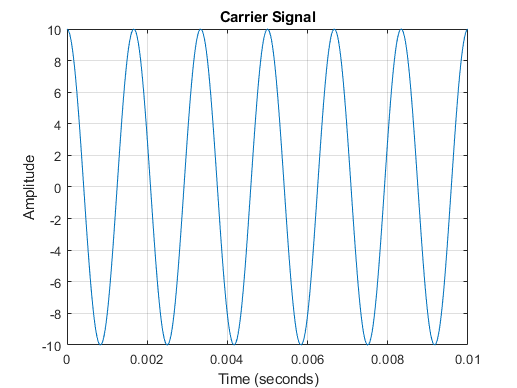


% ============ FIXED: Create carrier with AUDIO's sampling rate ============
% Use audio's sampling rate for everything
Fs = audio_fs;  % This is the correct sampling rate
duration_audio = length(m_t) / Fs;
t = (0:length(m_t)-1)' / Fs;  % Time vector matching audio

% Create the carrier signal with CORRECT sampling rate
c_t = A_c * cos(2 * pi * F_c * t);
% ==========================================================================

% Plot the carrier signal (just first few milliseconds)
figure;
plot(t, c_t);
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Carrier Signal');
grid on;
xlim([0, min(0.01, duration_audio)]);  % Show first 10ms

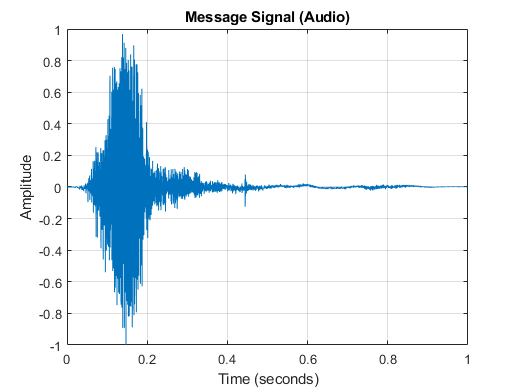


% Create the AM signal
S_t = A_c * (1 + K_a * m_t) .* cos(2 * pi * F_c * t);

% Plot message signal
figure;
plot(t, m_t);
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Message Signal (Audio)');
grid on;
xlim([0, min(1, duration_audio)]);  % Show first second

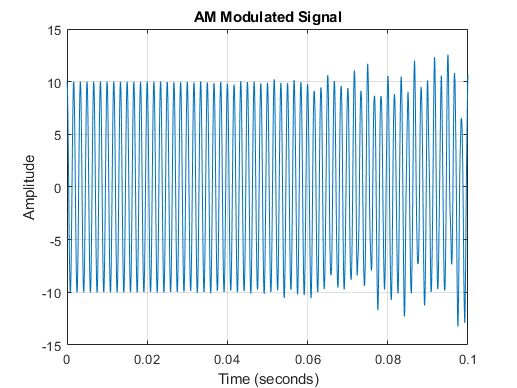


% Plot the modulated signal
figure;
plot(t(1:min(10000, length(t))), S_t(1:min(10000, length(t))));  % Plot first 10000 samples only
xlabel('Time (seconds)');
ylabel('Amplitude');
title('AM Modulated Signal');
grid on;
xlim([0, min(0.1, duration_audio)]);  % Show first 0.1 seconds

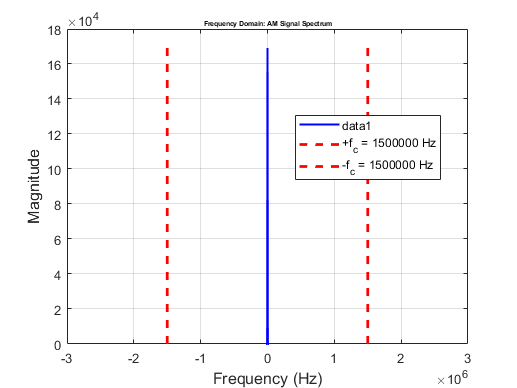


%% FREQUENCY DOMAIN ANALYSIS OF AM SIGNAL

% Calculate FFT of the modulated signal
N = length(S_t);  % Number of samples

% Ensure N is even for fftshift
if mod(N, 2) == 1
    N = N - 1;  % Make N even
    S_t = S_t(1:N);
    t = t(1:N);
end

S_f = fft(S_t, N);  % Compute FFT

% Create frequency axis (in Hz)
frequencies = linspace(-Fs/2, Fs/2, N+1);
frequencies = frequencies(1:end-1);  % Remove duplicate point
S_f_shifted = fftshift(S_f);

% Plot frequency spectrum
figure;
plot(frequencies, abs(S_f_shifted), 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)', 'FontSize', 12);
ylabel('Magnitude', 'FontSize', 12);
title('Frequency Domain: AM Signal Spectrum', 'FontSize', 5, 'FontWeight', 'bold');
grid on;

% Mark carrier frequency
hold on;
plot([F_c, F_c], [0, max(abs(S_f_shifted))], 'r--', 'LineWidth', 2, 'DisplayName', sprintf('+f_c = %.0f Hz', F_c));
plot([-F_c, -F_c], [0, max(abs(S_f_shifted))], 'r--', 'LineWidth', 2, 'DisplayName', sprintf('-f_c = %.0f Hz', F_c));
legend('Location', 'best');

% Zoom around carrier frequency to see sidebands
xlim([-F_c*2, F_c*2]);  % Show from -2f_c to +2f_c
hold off;

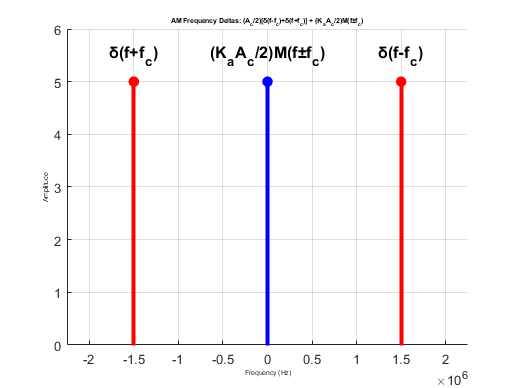


%% PLOT FREQUENCY DELTAS
figure;
hold on;

% Delta 1: Carrier at +f_c
stem(F_c, A_c/2, 'r', 'LineWidth', 3, 'MarkerSize', 5, 'MarkerFaceColor', 'r');

% Delta 2: Carrier at -f_c  
stem(-F_c, A_c/2, 'r', 'LineWidth', 3, 'MarkerSize', 5, 'MarkerFaceColor', 'r');

% Delta 3: Sidebands
stem(0, K_a*A_c/2, 'b', 'LineWidth', 3, 'MarkerSize', 5, 'MarkerFaceColor', 'b');

hold off;
xlabel('Frequency (Hz)', 'FontSize', 5);
ylabel('Amplitude', 'FontSize', 5);
title(sprintf('AM Frequency Deltas: (A_c/2)[δ(f-f_c)+δ(f+f_c)] + (K_aA_c/2)M(f±f_c)'), ...
      'FontSize', 5, 'FontWeight', 'bold');
grid on;
xlim([-F_c*1.5, F_c*1.5]);
ylim([0, max(A_c/2, K_a*A_c/2)*1.2]);

% Add labels
text(F_c, A_c/2*1.1, 'δ(f-f_c)', 'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
text(-F_c, A_c/2*1.1, 'δ(f+f_c)', 'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');
text(0, K_a*A_c/2*1.1, '(K_aA_c/2)M(f±f_c)', 'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold');


%% ============================================
% DEMODULATION: RECOVER ORIGINAL MESSAGE
% ============================================
fprintf('\n=== DEMODULATION PROCESS ===\n');


=== DEMODULATION PROCESS ===



%% METHOD 1: ENVELOPE DETECTION
fprintf('\n--- Method 1: Envelope Detection ---\n');


--- Method 1: Envelope Detection ---



% Step 1: Rectify the AM signal
rectified_S_t = abs(S_t);

% Step 2: Design low-pass filter
cutoff_freq = 5000;  % 5 kHz cutoff

fprintf('Designing low-pass filter with cutoff: %.0f Hz\n', cutoff_freq);

Designing low-pass filter with cutoff: 5000 Hz



% Create FIR low-pass filter
filter_order = 100;
lpFilt = designfilt('lowpassfir', 'FilterOrder', filter_order, ...
                    'CutoffFrequency', cutoff_freq, ...
                    'SampleRate', Fs);

% Step 3: Apply low-pass filter to extract envelope
envelope = filtfilt(lpFilt, rectified_S_t);

% Step 4: Remove DC offset (A_c term)
demodulated_signal = (envelope - mean(envelope)) / (A_c * K_a);

% Scale to match original range
demodulated_signal = demodulated_signal / max(abs(demodulated_signal));

fprintf('Demodulation completed\n');

Demodulation completed


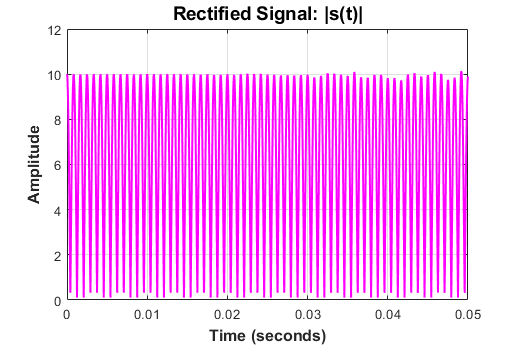


%% PLOT 1: RECTIFIED SIGNAL
figure('Name', 'Rectified Signal', 'Position', [100, 550, 600, 400]);
plot(t, rectified_S_t, 'm', 'LineWidth', 1.5);
xlabel('Time (seconds)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Amplitude', 'FontSize', 12, 'FontWeight', 'bold');
title('Rectified Signal: |s(t)|', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
xlim([0, min(0.05, duration_audio)]);

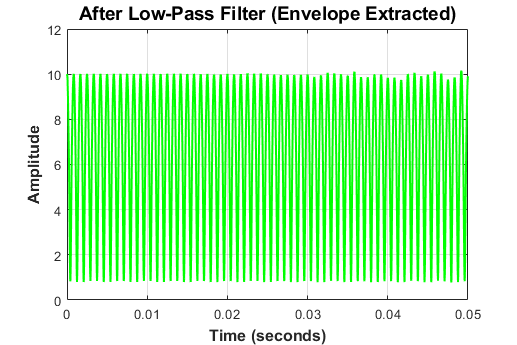


%% PLOT: After Low-Pass Filter
figure('Name', 'After Low-Pass Filter', 'NumberTitle', 'off', 'Position', [1400, 100, 600, 400]);
plot(t, envelope, 'g', 'LineWidth', 1.5);
xlabel('Time (seconds)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Amplitude', 'FontSize', 12, 'FontWeight', 'bold');
title('After Low-Pass Filter (Envelope Extracted)', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
xlim([0, min(0.05, duration_audio)]);

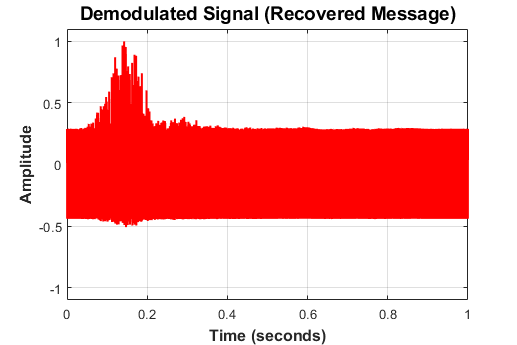


%% PLOT 2: DEMODULATED SIGNAL
figure('Name', 'Demodulated Signal', 'Position', [750, 550, 600, 400]);
plot(t, demodulated_signal, 'r', 'LineWidth', 1.5);
xlabel('Time (seconds)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Amplitude', 'FontSize', 12, 'FontWeight', 'bold');
title('Demodulated Signal (Recovered Message)', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
xlim([0, min(1, duration_audio)]);
ylim([-1.1, 1.1]);


%% AUDIO PLAYBACK
fprintf('\n=== AUDIO PLAYBACK ===\n');


=== AUDIO PLAYBACK ===



% Normalize signals for playback
m_t_play = m_t / max(abs(m_t));
demod_play = demodulated_signal / max(abs(demodulated_signal));

% Limit playback to first 5 seconds
play_duration = 5;  % seconds
play_samples = min(length(m_t_play), round(play_duration * Fs));

fprintf('Playing first %d seconds...\n', play_duration);

Playing first 5 seconds...



% Play original message
fprintf('\n▶️ Playing ORIGINAL message...\n');


▶️ Playing ORIGINAL message...


sound(m_t_play(1:play_samples), Fs);
pause(play_duration + 1);

% Play demodulated signal
fprintf('▶️ Playing DEMODULATED signal...\n');

▶️ Playing DEMODULATED signal...


sound(demod_play(1:play_samples), Fs);

fprintf('\n=== DEMODULATION COMPLETE ===\n');


=== DEMODULATION COMPLETE ===
